# Load the image

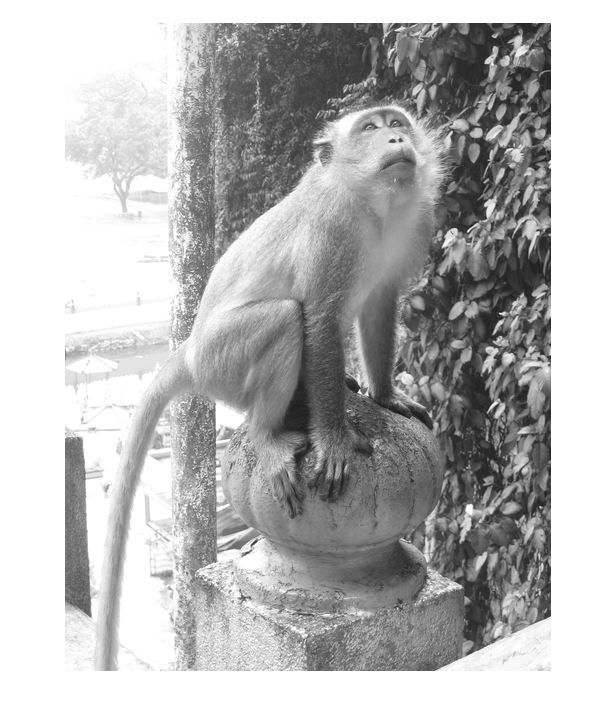

img = imread('yellowlily.jpg');
img = imread('onion.png');
img = imread('westconcordorthophoto.png');
img = imread('pout.tif');
img = imread('monkey.png');
% 
% img = imread('hestain.png');
% img = imread('snowflakes.png');
% img = imread('daisies.png');
% img = imread('cameraman.tif');

figure, imshow(img);

## Use fspecial to create an average filter

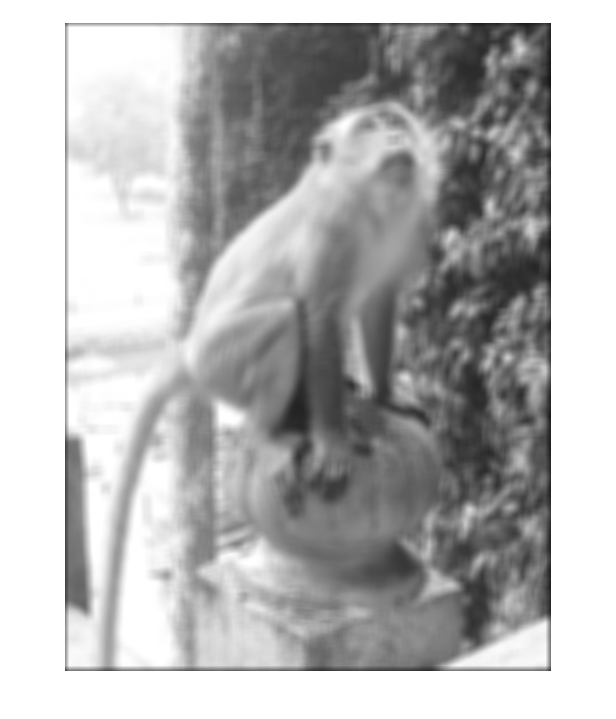

%The function below produces a 10 x 10 averaging filter. 
%Use "help fspecial" to figure out how to specify a different filter size

f = fspecial('average', 10); 

imavg = imfilter(img, f); %Default behavior: The output array is the same size as the input array.
figure, imshow(imavg)

fprintf("Size of img is [%d, %d]", size(img,1), size(img,2));

Size of img is [648, 486]

fprintf("Size of imavg is [%d, %d]", size(imavg,1), size(imavg,2));

Size of imavg is [648, 486]

## Effect of dealing with the border

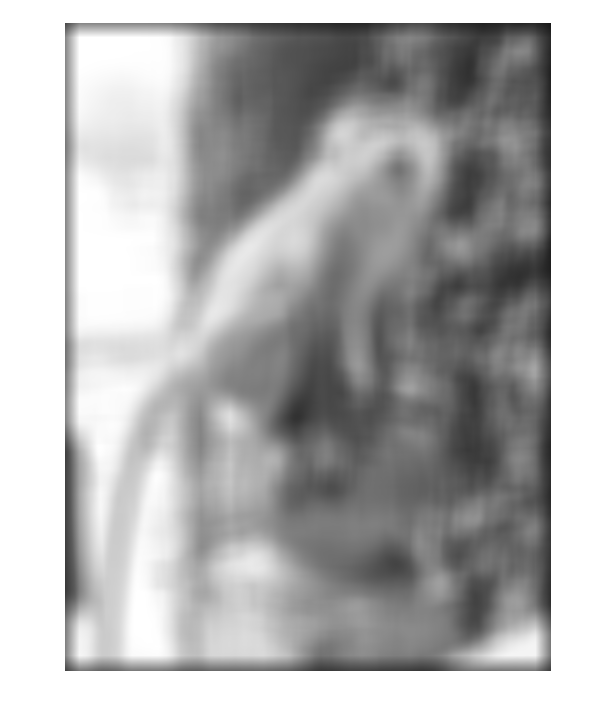

%Test this module with monkey.png
%Change the images and visually examine the differences between different
%ways of dealing with the border issue

f = fspecial('average', 30);

%Zero padding (default case)
imavg = imfilter(img, f);
figure, imshow(imavg)

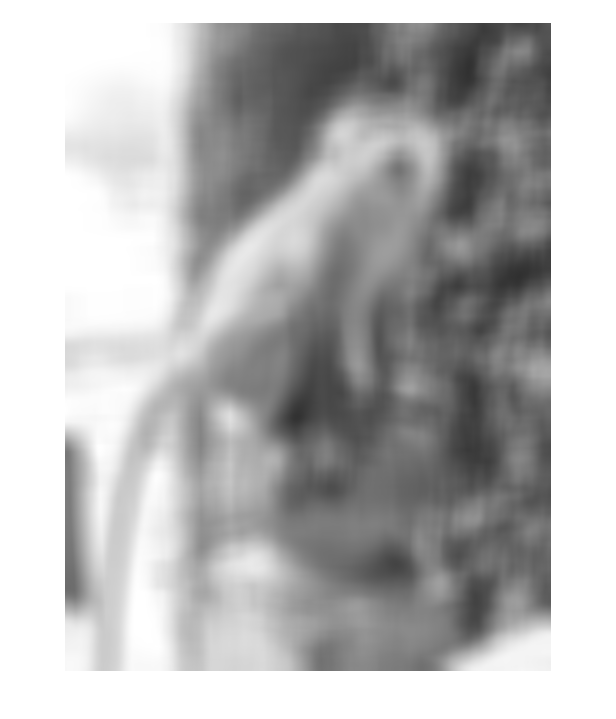


%Reflection
imavg = imfilter(img, f, 'symmetric');
figure, imshow(imavg)

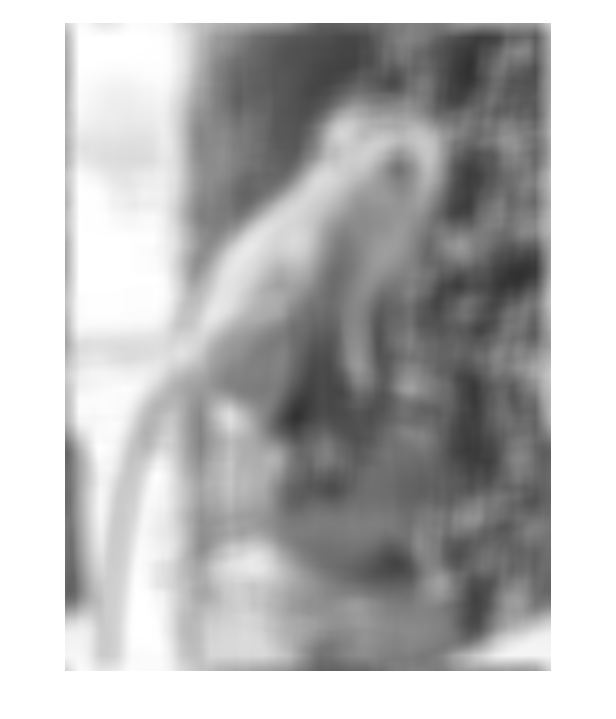


%Tiled Repetition
imavg = imfilter(img, f, 'circular');
figure, imshow(imavg)

## Create a gaussian filter using Matlab's implementation (fspecial) 

%This produces a filter with default size of 3 x 3 and sigma = 0.5. 
%Both can be specified using syntax f = fspecial('gaussian', winSize, sigma)
f = fspecial('gaussian') 

f =     0.0113    0.0838    0.0113
    0.0838    0.6193    0.0838
    0.0113    0.0838    0.0113


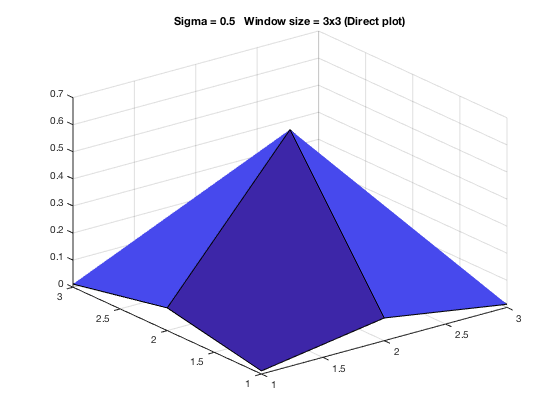


%Plot the filter f. Note that it's low resolution (under-sampled)
%because f is a discrete approximation of a continuous gaussian function.
%In particular, for the default filter size of 3 x 3, f computes the Gaussian value at x, y = -1, 0, 1 
winSize = 3;
sigma = 0.5;
x = 1:winSize;
y = 1:winSize;
figure, surf(x, y, f) 
title(['Sigma = ', num2str(sigma), '   Window size = ', num2str(winSize),'x', num2str(winSize), ' (Direct plot)'])

## Examine gaussian filter of different sizes but fixed standard deviation

Let us apply gaussian filter of different sizes but fixed standard deviation

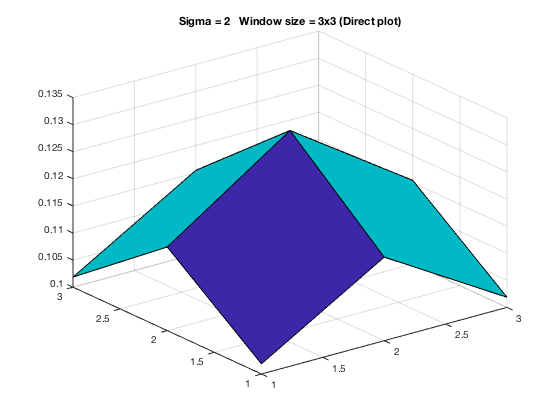

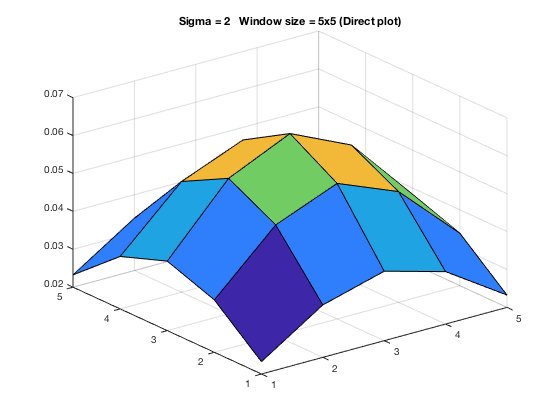

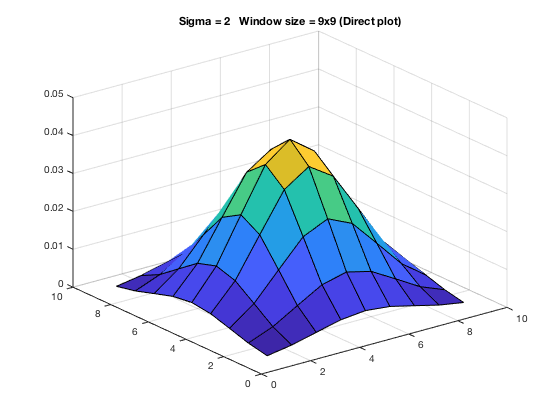

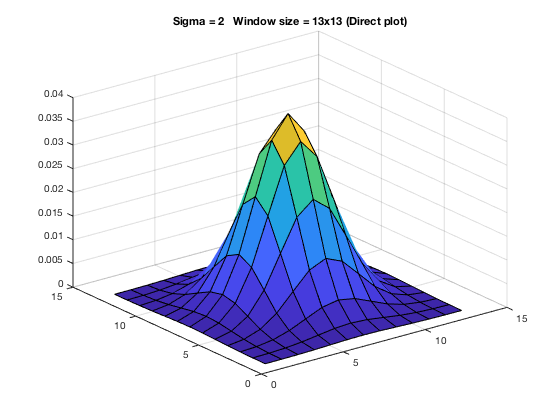

sigma = 2;
%Examine filters of sizes ranging 3 x 3 to 9 x 9
for winSize=[3, 5, 9, 13]
    f = fspecial('gaussian', winSize, sigma);
    x = 1:winSize;
    y = 1:winSize;
    figure, surf(x, y, f) 
    title(['Sigma = ', num2str(sigma), '   Window size = ', num2str(winSize),'x', num2str(winSize), ' (Direct plot)'])    
end

## Examine gaussian filter of different standard deviations (filter size calculated automatically)

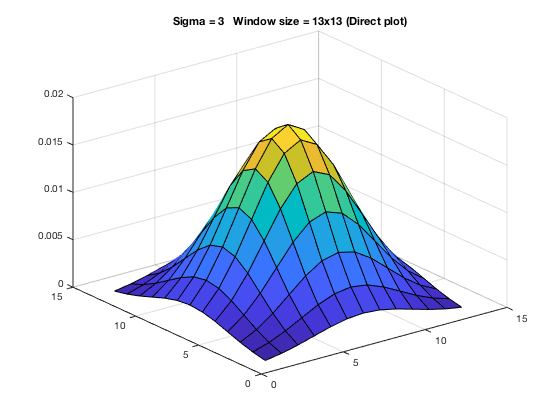

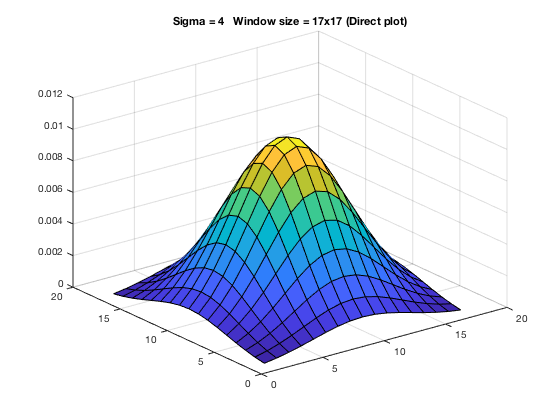


%Examine filters of sigma ranging from 1 to 4
for sigma=2:4
%     f = fspecial('gaussian', winSize, sigma);
    f = fspecial('gaussian', [], sigma);
    winSize = 2*ceil(2*sigma)+1;
    x = 1:winSize;
    y = 1:winSize;
    figure, surf(x, y, f) 
    title(['Sigma = ', num2str(sigma), '   Window size = ', num2str(winSize),'x', num2str(winSize), ' (Direct plot)'])    

end